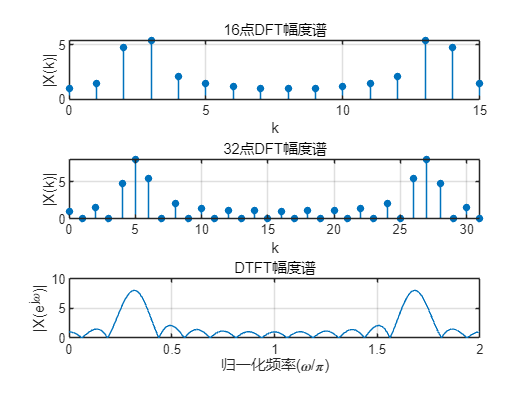

% 定义16点序列
n = 0:15;                                   % 定义n的范围0-15
x = cos(5*pi/16 * n);                       % 生成16点余弦序列

% 计算16点DFT
X_16 = fft(x, 16);                          % 计算16点DFT
mag_X_16 = abs(X_16);                       % 计算幅度谱

% 计算32点DFT
X_32 = fft(x, 32);                          % 计算32点DFT（补零到32点）
mag_X_32 = abs(X_32);                       % 计算幅度谱

% 计算DTFT
[H, W] = freqz(x, 1, 1024, 'whole');        % 计算1024点的DTFT
mag_H = abs(H);                             % 计算幅度谱

% 绘制图形
figure;

% 16点DFT幅度谱
subplot(3,1,1);
stem(0:15, mag_X_16, 'filled', 'MarkerSize', 4);
title('16点DFT幅度谱');
xlabel('k'); ylabel('|X(k)|');
xlim([0 15]); grid on;

% 32点DFT幅度谱
subplot(3,1,2);
stem(0:31, mag_X_32, 'filled', 'MarkerSize', 4);
title('32点DFT幅度谱');
xlabel('k'); ylabel('|X(k)|');
xlim([0 31]); grid on;

% DTFT幅度谱
subplot(3,1,3);
plot(W/pi, mag_H);
title('DTFT幅度谱');
xlabel('归一化频率(\omega/\pi)'); ylabel('|X(e^{j\omega})|');
xlim([0 2]); grid on;